clear;
new_name = convert_format(2);

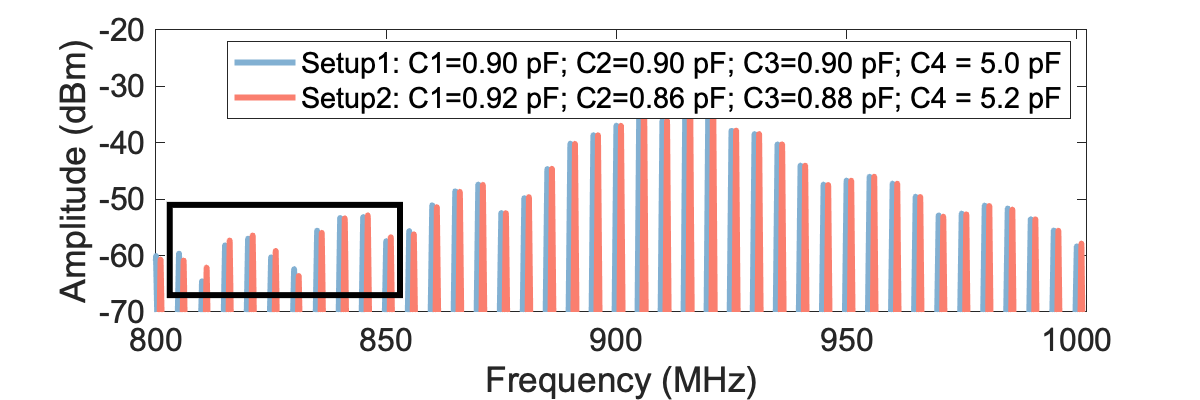

%% big figure
[f,data1] = read_raw('./voltage_multiplier_2stage_1.raw');
[~,data2] = read_raw('./voltage_multiplier_2stage_2.raw');

now_figure = figure("Position",[0,0,600,200]);
data1 = 10*log10(data1);
plot(f/1E6,data1,'DisplayName','Setup1: C1=0.90 pF; C2=0.90 pF; C3=0.90 pF; C4 = 5.0 pF','LineWidth',3,'Color',[130 176 210]/255);
hold on;

data2 = 10*log10(data2);
shift_data = zeros(size(data2));
shift_data(1:2) = [-80,-80];
shift_data(3:end) = data2(1:end-2);
loglog(f/1E6,shift_data,'DisplayName','Setup2: C1=0.92 pF; C2=0.86 pF; C3=0.88 pF; C4 = 5.2 pF','LineWidth',3,'Color',[250 127 111]/255);
hold off;
legend;
xlabel("Frequency (MHz)");
ylabel("Amplitude (dBm)");
xlim([800,1002]);
xticks((800:50:1000));
ylim([-70 -20]);
ax = gca;
set(ax, 'FontSize', 16, 'FontName','Arial');
rectangle('Position',[803 -67 50 16],'LineWidth',3);
exportgraphics(gcf,"./nonlinearity.pdf");


% print(now_figure, '-dpdf', 'nonlinearity.pdf');


%% small figure
now_figure = figure("Position",[0,0,600,600/16*9]);
plot(f/1E6,data1,'LineWidth',4,'Color',[130 176 210]/255);
hold on;
plot(f/1E6,shift_data,'LineWidth',4,'Color',[250 127 111]/255);
hold off;
xlim([809,843]);
ylim([-68 -50]);
ax = gca;  % 获取当前的坐标轴
set(ax, 'FontSize', 20, 'FontName','Arial');
set(ax, 'XTick', [], 'YTick', []);
axis off  % 关闭轴
print(now_figure, '-dpdf', 'nonlinearity-scaleup.pdf');

%%
% Plot the data
% subplot(2,1,1);
% plot(time, voltage);
% title('Voltage vs Time');
% xlabel('Time (s)');
% ylabel('Voltage (V)');
% 
% subplot(2,1,2);
% plot(time, current);
% title('Current vs Time');
% xlabel('Time (s)');
% ylabel('Current (A)');

function new_name = convert_format(index)
    name = "voltage_multiplier_2stage";
    fileID = fopen(name+".raw", 'rb');
    if fileID == -1
        error('Failed to open file');
    end
    data = fread(fileID);
    fclose(fileID);

    % 移除所有的NULL字节（ASCII值为0的字节）
    new_name = name+"_"+num2str(index)+".raw";
    data(data == 0) = [];
    newFileID = fopen(new_name, 'wb');
    fwrite(newFileID, data);
    fclose(newFileID);
end


function [f,current_fft_useful] = read_raw(name)
    fileID = fopen(name);
    for i = 1:13
        fgetl(fileID);
    end
    data = textscan(fileID, "%*f\t\t%f\n\t%f\n\t%f\n", [Inf 3]);
    time = data{1};
    voltage = data{2};
    current = data{3};
    fclose(fileID);
    uniform_time = (0:1E-10:2E-06)';
    uniform_current = interp1(time, current, uniform_time);

    L = size(uniform_current(1:end-1),1);
    current_fft = abs(fft(uniform_current(1:end-1))/L);
    current_fft  = current_fft(1:L/2+1);
    T = 2E-06/L;
    Fs = 1/T;
    f = Fs*(0:(L/2))/L;
    % target frequency band 800MHz - 1049.5MHz
    current_fft_useful = current_fft(1600:2101);
    f = f(1600:2101);
end
